# Plot Syllable Acoustics

## Step 1: Quantify Acoustics

Quantify the acoustics of individual syllables. For each syllable, the calculated acoustics will be saved in the '*.not.mat' file.

bird = 'br177yw112';
syls ='d'% ['doae'];

syls = 'd'


for i = 1:length(syls)
    this_syll = syls(i);
    QuantPitchContours_leila(this_syll,1024,1020,1.0)
    quantify_acoustics(this_syll,1,'mat');
end    

Found 5 examples of 'd' in br173gr56_220627_124700_songbout1.mat.not.mat
    {'Sampling frequency (Fs) for br173gr56_220627_124700_songbout1.matequals 30000 instead of 32000'}    {'click 'OK' to resample with ratio 16 / 15'}    {'otherwise click 'Quit' and copy files with this Fs'}    {'to a different folder to prevent crashes'}



btn = 'OK'

Found 7 examples of 'd' in br173gr56_220627_124700_songbout3.mat.not.mat
Rendition 19  24  26  32  48  60  74 could not be converted to spectrogram
Found 1 examples of 'd' in br173gr56_220627_124900_songbout1.mat.not.mat
Found 0 examples of 'd' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 5 examples of 'd' in br173gr56_220627_125100_songbout1.mat.not.mat
Rendition 10  19  29  44  59 could not be converted to spectrogram
Found 9 examples of 'd' in br173gr56_220627_125200_songbout2.mat.not.mat
Rendition 5   17   33   41   65   75  105  117  126 could not be converted to spectrogram
Found 3 examples of 'd' in br173gr56_220627_125300_songbout1.mat.not.mat
Found 5 examples of 'd' in br173gr56_220627_125300_songbout3.mat.not.mat
Found 7 examples of 'd' in br173gr56_220627_125400_songbout1.mat.not.mat
Found 5 examples of 'd' in br173gr56_220627_125500_songbout1.mat.not.mat
Found 2 examples of 'd' in br173gr56_220627_125500_songbout2.mat.not.mat
Found 5 examples of 'd' in br173gr56_2

% QUERY: BIRD 1
% bird = 'br177yw112';
% days = [62 66 68 73 86 88];

% syls = ['epqrs'];

% QUERY: BIRD 2
bird = 'br173gr56';
days = [78 801 802 803 811 812 153];
syls = ['abcdefghjkopqrs'];

warning('on','all')
failedSyls ={};
for d= 1:length(days)
    day = days(d)
    [~,~,~,folder,~] = raster_params(bird,day);
    cd(folder)
    for i = 1:length(syls)
        try
        this_syll = syls(i)
        % QuantPitchContours_leila(this_syll,1024,1020,1.0)
        quantify_acoustics(this_syll,1,'mat');

        catch exception
            message = ['failed for: ' num2str(day) ' -syl ' syls(i)];
            failedSyls = [failedSyls; message];
            display(message)
        end
    end
end

day = 78

this_syll = 'a'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 0 examples of 'a' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 6 examples of 'a' in br173gr56_220627_125200_songbout2.mat.not.mat
Found 6 examples of 'a' in br173gr56_220627_140100_songbout2.mat.not.mat
Found 4 examples of 'a' in br173gr56_220627_140100_songbout3.mat.not.mat
Found 3 examples of 'a' in br173gr56_220627_124700_songbout3.mat.not.mat
Found 4 examples of 'a' in br173gr56_220627_125500_songbout1.mat.not.mat
Found 6 examples of 'a' in br173gr56_220627_125800_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'a' in br173gr56_220627_140000_songbout1.mat.not.mat
Found 3 examples of 'a' in br173gr56_220627_140000_songbout2.mat.not.mat
Found 2 examples of 'a' in br173gr56_220627_124700_songbout1.mat.not.mat
Found 5 examples of 'a' in br173gr56_220627_125700_songbout3.mat.not.mat
Found 3 examples of 'a' in br173gr

this_syll = 'b'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 0 examples of 'b' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 7 examples of 'b' in br173gr56_220627_125200_songbout2.mat.not.mat
Found 7 examples of 'b' in br173gr56_220627_140100_songbout2.mat.not.mat
Found 5 examples of 'b' in br173gr56_220627_140100_songbout3.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 5 examples of 'b' in br173gr56_220627_124700_songbout3.mat.not.mat
Found 5 examples of 'b' in br173gr56_220627_125500_songbout1.mat.not.mat
Found 4 examples of 'b' in br173gr56_220627_125800_songbout1.mat.not.mat
Found 4 examples of 'b' in br173gr56_220627_140000_songbout1.mat.not.mat
Found 4 examples of 'b' in br173gr56_220627_140000_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'b' in br173gr56_220627_124700_songbout1.mat.not.mat
Found 4 examples of 'b' in br173gr56_220627_125700_songbout3.ma

this_syll = 'c'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 0 examples of 'c' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 20 examples of 'c' in br173gr56_220627_125200_songbout2.mat.not.mat
Found 21 examples of 'c' in br173gr56_220627_140100_songbout2.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 16 examples of 'c' in br173gr56_220627_140100_songbout3.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 15 examples of 'c' in br173gr56_220627_124700_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 16 examples of 'c' in br173gr56_220627_125500_songbout1.mat.not.mat
Found 17 examples of 'c' in br173gr56_220627_125800_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Fou

this_syll = 'd'

This is for bird br173gr56
Window duration = 8 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 0 examples of 'd' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 9 examples of 'd' in br173gr56_220627_125200_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 10 examples of 'd' in br173gr56_220627_140100_songbout2.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 9 examples of 'd' in br173gr56_220627_140100_songbout3.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
Found 7 examples of 'd' in br173gr56_220627_124700_songbout3.mat.not.mat
Found 5 examples of 'd' in br173gr56_220627_125500_son

this_syll = 'e'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 0 examples of 'e' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 16 examples of 'e' in br173gr56_220627_125200_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
Found 13 examples of 'e' in br173gr56_220627_140100_songbout2.mat.not.mat
NBins = 1 rather than preferred value of 3
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 12 examples of 'e' in br173gr56_220627_140100_songbout3.mat.not.mat
NBins = 1 rather than preferred value o

this_syll = 'f'

f


f
This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 0 examples of 'f' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 7 examples of 'f' in br173gr56_220627_125200_songbout2.mat.not.mat
Found 6 examples of 'f' in br173gr56_220627_140100_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 4 examples of 'f' in br173gr56_220627_140100_songbout3.mat.not.mat
Found 5 examples of 'f' in br173gr56_220627_124700_songbout3.mat.not.mat
Found 5 examples of 'f' in br173gr56_220627_125500_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 4 examples of 'f' in br173gr56_220627_125800_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 4 examples of 'f' in br173gr56_220627_140000

this_syll = 'g'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 0 examples of 'g' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 7 examples of 'g' in br173gr56_220627_125200_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 6 examples of 'g' in br173gr56_220627_140100_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'g' in br173gr56_220627_140100_songbout3.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 4 examples of 'g' in br173gr56_220627_124700_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'g' in br173gr56_220627_125500_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'g' in br173gr56_220627_125800_songbout1.mat.not.mat
Found 4 examples of 'g' in br173gr56_220627_140000_s

this_syll = 'h'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 0 examples of 'h' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 7 examples of 'h' in br173gr56_220627_125200_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 6 examples of 'h' in br173gr56_220627_140100_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'h' in br173gr56_220627_140100_songbout3.mat.not.mat
Found 3 examples of 'h' in br173gr56_220627_124700_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 4 examples of 'h' in br173gr56_220627_125500_songbout1.mat.not.mat
Found 3 examples of 'h' in br173gr56_220627_125800_songbout1.mat.not.mat
Found 4 examples of 'h' in br173gr56_220627_140000_songbout1.mat.not.mat
Found 4 examples of 'h

this_syll = 'j'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=70 with freq cutoff at [500  2000]
Found 0 examples of 'j' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 11 examples of 'j' in br173gr56_220627_125200_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 13 examples of 'j' in br173gr56_220627_140100_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 10 examples of 'j' in br173gr56_220627_140100_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPE

this_syll = 'k'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2200]
Found 0 examples of 'k' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 11 examples of 'k' in br173gr56_220627_125200_songbout2.mat.not.mat
NBins = 1 rather than preferred value of 3
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 13 examples of 'k' in br173gr56_220627_140100_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking

this_syll = 'o'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 0 examples of 'o' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 5 examples of 'o' in br173gr56_220627_125200_songbout2.mat.not.mat
Found 7 examples of 'o' in br173gr56_220627_140100_songbout2.mat.not.mat
Found 6 examples of 'o' in br173gr56_220627_140100_songbout3.mat.not.mat
Found 8 examples of 'o' in br173gr56_220627_124700_songbout3.mat.not.mat
Found 6 examples of 'o' in br173gr56_220627_125500_songbout1.mat.not.mat
Found 4 examples of 'o' in br173gr56_220627_125800_songbout1.mat.not.mat
Found 4 examples of 'o' in br173gr56_220627_140000_songbout1.mat.not.mat
Found 3 examples of 'o' in br173gr56_220627_140000_songbout2.mat.not.mat
Found 5 examples of 'o' in br173gr56_220627_124700_songbout1.mat.not.mat
Found 3 examples of 'o' in br173gr56_220627_125700_songbout3.mat.not.mat
Found 6 examples of 'o' in br173gr56_220627_125700_songbout1.mat.not.mat
Fou

this_syll = 'p'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2000]
Found 0 examples of 'p' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 6 examples of 'p' in br173gr56_220627_125200_songbout2.mat.not.mat
Found 6 examples of 'p' in br173gr56_220627_140100_songbout2.mat.not.mat
Found 4 examples of 'p' in br173gr56_220627_140100_songbout3.mat.not.mat
Found 5 examples of 'p' in br173gr56_220627_124700_songbout3.mat.not.mat
Found 3 examples of 'p' in br173gr56_220627_125500_songbout1.mat.not.mat
Found 3 examples of 'p' in br173gr56_220627_125800_songbout1.mat.not.mat
Found 5 examples of 'p' in br173gr56_220627_140000_songbout1.mat.not.mat
Found 5 examples of 'p' in br173gr56_220627_140000_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'p' in br173gr56_220627_124700_songbout1.mat.not.mat
Found 2 examples of 'p' in br173gr56_220627_125700_songbout3.mat.not.mat
NBins = 2 rather than preferred v

this_syll = 'q'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1200  2700]
Found 0 examples of 'q' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 6 examples of 'q' in br173gr56_220627_125200_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 6 examples of 'q' in br173gr56_220627_140100_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'q' in br173gr56_220627_140100_songbout3.mat.not.mat
Found 5 examples of 'q' in br173gr56_220627_124700_songbout3.mat.not.mat
Found 3 examples of 'q' in br173gr56_220627_125500_songbout1.mat.not.mat
Found 3 examples of 'q' in br173gr56_220627_125800_songbout1.mat.not.mat
Found 5 examples of 'q' in br173gr56_220627_140000_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'q' in br173gr56_220627_140000_songbout2.mat.not.mat
Found 5 examples of 'q' in br173gr56_220627_124700_songbout1.mat.not.mat
NBins = 2 rather tha

this_syll = 'r'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 0 examples of 'r' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 6 examples of 'r' in br173gr56_220627_125200_songbout2.mat.not.mat
Found 6 examples of 'r' in br173gr56_220627_140100_songbout2.mat.not.mat
Found 4 examples of 'r' in br173gr56_220627_140100_songbout3.mat.not.mat
Found 5 examples of 'r' in br173gr56_220627_124700_songbout3.mat.not.mat
Found 3 examples of 'r' in br173gr56_220627_125500_songbout1.mat.not.mat
Found 3 examples of 'r' in br173gr56_220627_125800_songbout1.mat.not.mat
Found 5 examples of 'r' in br173gr56_220627_140000_songbout1.mat.not.mat
Found 5 examples of 'r' in br173gr56_220627_140000_songbout2.mat.not.mat
Found 5 examples of 'r' in br173gr56_220627_124700_songbout1.mat.not.mat
Found 2 examples of 'r' in br173gr56_220627_125700_songbout3.mat.not.mat
Found 3 examples of 'r' in br173gr56_220627_125700_songbout1.mat.not.mat
Fou

this_syll = 's'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 0 examples of 's' in br173gr56_220627_124900_songbout2.mat.not.mat
Found 6 examples of 's' in br173gr56_220627_125200_songbout2.mat.not.mat
Found 6 examples of 's' in br173gr56_220627_140100_songbout2.mat.not.mat
Found 4 examples of 's' in br173gr56_220627_140100_songbout3.mat.not.mat
Found 5 examples of 's' in br173gr56_220627_124700_songbout3.mat.not.mat
Found 3 examples of 's' in br173gr56_220627_125500_songbout1.mat.not.mat
Found 3 examples of 's' in br173gr56_220627_125800_songbout1.mat.not.mat
Found 5 examples of 's' in br173gr56_220627_140000_songbout1.mat.not.mat
Found 5 examples of 's' in br173gr56_220627_140000_songbout2.mat.not.mat
Found 5 examples of 's' in br173gr56_220627_124700_songbout1.mat.not.mat
Found 2 examples of 's' in br173gr56_220627_125700_songbout3.mat.not.mat
Found 3 examples of 's' in br173gr56_220627_125700_songbout1.mat.not.mat
Fou

day = 801

this_syll = 'a'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 2 examples of 'a' in br173gr56_220629_105810_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 1 examples of 'a' in br173gr56_220629_105810_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 1 examples of 'a' in br173gr56_220629_105810_songbout3.mat.not.mat
Found 1 examples of 'a' in br173gr56_220629_105810_songbout4.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 0 examples of 'a' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 1 examples of 'a' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 1 examples of 'a' in br173gr56_220629_105910_songbout3.mat.not.mat
Found 2 examples of 'a' in br173gr56_2

this_syll = 'b'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 3 examples of 'b' in br173gr56_220629_105810_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 1 examples of 'b' in br173gr56_220629_105810_songbout2.mat.not.mat
Found 1 examples of 'b' in br173gr56_220629_105810_songbout3.mat.not.mat
Found 1 examples of 'b' in br173gr56_220629_105810_songbout4.mat.not.mat
Found 1 examples of 'b' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 2 examples of 'b' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 4 examples of 'b' in br173gr56_220629_105910_songbout3.mat.not.mat
Found 3 examples of 'b' in br173gr56_220629_105910_songbout4.mat.not.mat
Found 1 examples of 'b' in br173gr56_220629_105910_songbout5.mat.not.mat
Found 1 examples of 'b' in br173gr56_220629_105910_songbout6.mat.not.mat
Found 2 examples of 'b' in br173gr56_220629_110010_songbout1.mat.not.mat
Found 5 examples of 'b' in br173g

this_syll = 'c'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 10 examples of 'c' in br173gr56_220629_105810_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'c' in br173gr56_220629_105810_songbout2.mat.not.mat
Found 6 examples of 'c' in br173gr56_220629_105810_songbout3.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 4 examples of 'c' in br173gr56_220629_105810_songbout4.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'c' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 7 examples of 'c' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 6 examples of 'c' in br173gr56_220629_105910_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 9 examples of 'c' in br173gr56_220629_105910_songbout4.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'c' in br173gr56_220629_105910_songbout5.mat.not.mat
Found 

this_syll = 'd'

This is for bird br173gr56
Window duration = 8 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 1 examples of 'd' in br173gr56_220629_105810_songbout1.mat.not.mat
Found 1 examples of 'd' in br173gr56_220629_105810_songbout2.mat.not.mat
Found 1 examples of 'd' in br173gr56_220629_105810_songbout3.mat.not.mat
Found 1 examples of 'd' in br173gr56_220629_105810_songbout4.mat.not.mat
Found 0 examples of 'd' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 2 examples of 'd' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 3 examples of 'd' in br173gr56_220629_105910_songbout3.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 3 examples of 'd' in br173gr56_220629_105910_songbout4.mat.not.mat
Found 1 examples of 'd' in br173gr56_220629_105910_songbout5.mat.not.mat
Found 1 examples of 'd' in br173gr56_220629_105910_songbout6.mat.not.mat
Peak a

this_syll = 'e'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 8 examples of 'e' in br173gr56_220629_105810_songbout1.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
Found 7 examples of 'e' in br173gr56_220629_105810_songbout2.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak b

this_syll = 'f'

f


f
This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 3 examples of 'f' in br173gr56_220629_105810_songbout1.mat.not.mat
Found 1 examples of 'f' in br173gr56_220629_105810_songbout2.mat.not.mat
Found 1 examples of 'f' in br173gr56_220629_105810_songbout3.mat.not.mat
Found 1 examples of 'f' in br173gr56_220629_105810_songbout4.mat.not.mat
Found 1 examples of 'f' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 2 examples of 'f' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 3 examples of 'f' in br173gr56_220629_105910_songbout3.mat.not.mat
Found 3 examples of 'f' in br173gr56_220629_105910_songbout4.mat.not.mat
Found 1 examples of 'f' in br173gr56_220629_105910_songbout5.mat.not.mat
Found 1 examples of 'f' in br173gr56_220629_105910_songbout6.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 2 examples of 'f' in br173gr56_220629_110010_songbout1.mat.not.mat
Found 5 examples of 'f' in br17

this_syll = 'g'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 2 examples of 'g' in br173gr56_220629_105810_songbout1.mat.not.mat
Found 0 examples of 'g' in br173gr56_220629_105810_songbout2.mat.not.mat
Found 1 examples of 'g' in br173gr56_220629_105810_songbout3.mat.not.mat
Found 1 examples of 'g' in br173gr56_220629_105810_songbout4.mat.not.mat
Found 1 examples of 'g' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 2 examples of 'g' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 2 examples of 'g' in br173gr56_220629_105910_songbout3.mat.not.mat
Found 3 examples of 'g' in br173gr56_220629_105910_songbout4.mat.not.mat
Found 1 examples of 'g' in br173gr56_220629_105910_songbout5.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 1 examples of 'g' in br173gr56_220629_105910_songbout6.mat.not.mat
Found 2 examples of 'g' in br173gr56_220629_110010_songbout1.mat.not.mat
Found 3 examples of 'g' in br173g

this_syll = 'h'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 2 examples of 'h' in br173gr56_220629_105810_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 0 examples of 'h' in br173gr56_220629_105810_songbout2.mat.not.mat
Found 1 examples of 'h' in br173gr56_220629_105810_songbout3.mat.not.mat
Found 1 examples of 'h' in br173gr56_220629_105810_songbout4.mat.not.mat
Found 1 examples of 'h' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 2 examples of 'h' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 2 examples of 'h' in br173gr56_220629_105910_songbout3.mat.not.mat
Found 1 examples of 'h' in br173gr56_220629_105910_songbout4.mat.not.mat
Found 1 examples of 'h' in br173gr56_220629_105910_songbout5.mat.not.mat
Found 0 examples of 'h' in br173gr56_220629_105910_songbout6.mat.not.mat
Found 2 examples of 'h' in br173gr56_220629_110010_songbout1.ma

this_syll = 'j'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=70 with freq cutoff at [500  2000]
Found 6 examples of 'j' in br173gr56_220629_105810_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
Found 2 examples of 'j' in br173gr56_220629_105810_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 2 examples of 'j' in br173gr56_220629_105810_songbout3.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 1 examples of 'j' in br173gr56_220629_105810_songbout4.mat.not.mat
Found 1 examples of 'j' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 4 examples of 'j' in br173gr56_220629_105910_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'j' in br173gr56_220629_105910_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 exam

this_syll = 'k'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2200]
Found 5 examples of 'k' in br173gr56_220629_105810_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 2 examples of 'k' in br173gr56_220629_105810_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 2 examples of 'k' in br173gr56_220629_105810_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 2 examples of 'k' in br173gr56_220629_105810_songbout4.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 1 examples of 'k' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 4 examples of 'k' in br173gr56_220629_105910_songbout2.mat.not.mat
NBins = 1 rather than preferred value o

this_syll = 'o'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 3 examples of 'o' in br173gr56_220629_105810_songbout1.mat.not.mat
Found 1 examples of 'o' in br173gr56_220629_105810_songbout2.mat.not.mat
Found 1 examples of 'o' in br173gr56_220629_105810_songbout3.mat.not.mat
Found 1 examples of 'o' in br173gr56_220629_105810_songbout4.mat.not.mat
Found 2 examples of 'o' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 2 examples of 'o' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 4 examples of 'o' in br173gr56_220629_105910_songbout3.mat.not.mat
Found 3 examples of 'o' in br173gr56_220629_105910_songbout4.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 1 examples of 'o' in br173gr56_220629_105910_songbout5.mat.not.mat
Found 3 examples of 'o' in br173gr56_220629_105910_songbout6.mat.not.mat
Found

message = 'failed for: 801 -syl o'

this_syll = 'p'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2000]
Found 3 examples of 'p' in br173gr56_220629_105810_songbout1.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_105810_songbout2.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_105810_songbout3.mat.not.mat
Found 0 examples of 'p' in br173gr56_220629_105810_songbout4.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 3 examples of 'p' in br173gr56_220629_105910_songbout3.mat.not.mat
Found 3 examples of 'p' in br173gr56_220629_105910_songbout4.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_105910_songbout5.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_105910_songbout6.mat.not.mat
Found 2 examples of 'p' in br173gr56_220629_110010_songbout1.mat.not.mat
Found 6 examples of 'p' in br173gr56_220629_110010_songbout2.mat.not.mat
Fou

this_syll = 'q'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1200  2700]
Found 2 examples of 'q' in br173gr56_220629_105810_songbout1.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_105810_songbout2.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_105810_songbout3.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_105810_songbout4.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 3 examples of 'q' in br173gr56_220629_105910_songbout3.mat.not.mat
Found 3 examples of 'q' in br173gr56_220629_105910_songbout4.mat.not.mat
Found 0 examples of 'q' in br173gr56_220629_105910_songbout5.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_105910_songbout6.mat.not.mat
Found 2 examples of 'q' in br173gr56_220629_110010_songbout1.mat.not.mat
Found 6 examples of 'q' in br173gr56_220629_110010_songbout2.mat.not.mat
Fou

this_syll = 'r'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 2 examples of 'r' in br173gr56_220629_105810_songbout1.mat.not.mat
Found 1 examples of 'r' in br173gr56_220629_105810_songbout2.mat.not.mat
Found 1 examples of 'r' in br173gr56_220629_105810_songbout3.mat.not.mat
Found 1 examples of 'r' in br173gr56_220629_105810_songbout4.mat.not.mat
Found 1 examples of 'r' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 1 examples of 'r' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 3 examples of 'r' in br173gr56_220629_105910_songbout3.mat.not.mat
Found 1 examples of 'r' in br173gr56_220629_105910_songbout4.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 0 examples of 'r' in br173gr56_220629_105910_songbout5.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_105910_songbout6.mat.not.mat
Found

this_syll = 's'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 2 examples of 's' in br173gr56_220629_105810_songbout1.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_105810_songbout2.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_105810_songbout3.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_105810_songbout4.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_105910_songbout1.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_105910_songbout2.mat.not.mat
Found 3 examples of 's' in br173gr56_220629_105910_songbout3.mat.not.mat
Found 3 examples of 's' in br173gr56_220629_105910_songbout4.mat.not.mat
Found 0 examples of 's' in br173gr56_220629_105910_songbout5.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_105910_songbout6.mat.not.mat
Found 2 examples of 's' in br173gr56_220629_110010_songbout1.mat.not.mat
Found 6 examples of 's' in br173gr56_220629_110010_songbout2.mat.not.mat
Fou

day = 802

this_syll = 'a'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 2 examples of 'a' in br173gr56_220629_150211_songbout1.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 1 examples of 'a' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 5 examples of 'a' in br173gr56_220629_151411_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 0 examples of 'a' in br173gr56_220629_151411_songbout2.mat.not.mat
Found 0 examples of 'a' in br173gr56_220629_151511_songbout1.mat.not.mat
Found 6 examples of 'a' in br173gr56_220629_151511_songbout2.mat.not.mat
Found 3 examples of 'a' in br173gr56_220629_151511_songbout3.mat.not

this_syll = 'b'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 1 examples of 'b' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 1 examples of 'b' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 6 examples of 'b' in br173gr56_220629_151411_songbout1.mat.not.mat
Found 2 examples of 'b' in br173gr56_220629_151411_songbout2.mat.not.mat
Found 1 examples of 'b' in br173gr56_220629_151511_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 6 examples of 'b' in br173gr56_220629_151511_songbout2.mat.not.mat
Found 5 examples of 'b' in br173gr56_220629_151511_songbout3.mat.not.mat
Found 2 examples of 'b' in br173gr56_220629_151511_songbout4.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'b' in br173gr56_220629_151611_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'b' in br173gr56_220629_151611_songbout2.mat.not.mat
Found 3 examples of 

this_syll = 'c'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 1 examples of 'c' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 6 examples of 'c' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 19 examples of 'c' in br173gr56_220629_151411_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 7 examples of 'c' in br173gr56_220629_151411_songbout2.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 2 examples of 'c' in br173gr56_220629_151511_songbout1.mat.not.mat
Found 20 examples of 'c' in br173gr56_220629_151511_songbout2.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 14 examples of 'c' in br173gr56_220629_151511_songbout3.mat.not.mat
Found 6 examples of 'c' in br173gr56_220629_151511_songbout4.mat.not.mat
Found 11 examples of 'c' in br173gr56_220629_151611_songbout1.mat.not.mat
Found 12 examples of 'c' in br173gr56_220629_1

this_syll = 'd'

This is for bird br173gr56
Window duration = 8 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 2 examples of 'd' in br173gr56_220629_150211_songbout1.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 1 examples of 'd' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 5 examples of 'd' in br173gr56_220629_151411_songbout1.mat.not.mat
Found 4 examples of 'd' in br173gr56_220629_151411_songbout2.mat.not.mat
Found 1 examples of 'd' in br173gr56_220629_151511_songbout1.mat.not.mat
Found 7 examples of 'd' in br173gr56_220629_151511_songbout2.mat.not.mat
Found 4 examples of 'd' in br173gr56_220629_151511_songbout3.mat.not.mat
Found 2 examples of 'd' in br173gr56_220629_151511_songbout4.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 1 

this_syll = 'e'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 1 examples of 'e' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 10 examples of 'e' in br173gr56_220629_151011_songbout1.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 13 examples of 'e' in br173gr56_220629_151411_songbout1.mat.not.mat
Peak at LOWER extreme of ra

this_syll = 'f'

f


f
This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 1 examples of 'f' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 1 examples of 'f' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 5 examples of 'f' in br173gr56_220629_151411_songbout1.mat.not.mat
Found 2 examples of 'f' in br173gr56_220629_151411_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 2 examples of 'f' in br173gr56_220629_151511_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 6 examples of 'f' in br173gr56_220629_151511_songbout2.mat.not.mat
Found 4 examples of 'f' in br173gr56_220629_151511_songbout3.mat.not.mat
Found 2 examples of 'f' in br173gr56_220629_151511_songbout4.mat.not.mat
Found 3 examples of 'f' in br173gr56_220629_151611_songbout1.mat.not.mat
Found 4 examples of 'f' in br173gr56_220629_151611_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather t

this_syll = 'g'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 1 examples of 'g' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 1 examples of 'g' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 4 examples of 'g' in br173gr56_220629_151411_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 2 examples of 'g' in br173gr56_220629_151411_songbout2.mat.not.mat
Found 2 examples of 'g' in br173gr56_220629_151511_songbout1.mat.not.mat
Found 5 examples of 'g' in br173gr56_220629_151511_songbout2.mat.not.mat
Found 3 examples of 'g' in br173gr56_220629_151511_songbout3.mat.not.mat
Found 2 examples of 'g' in br173gr56_220629_151511_songbout4.mat.not.mat
Found 3 examples of 'g' in br173gr56_220629_151611_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'g' in br173gr56_220629_151611_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather tha

this_syll = 'h'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 0 examples of 'h' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 1 examples of 'h' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 4 examples of 'h' in br173gr56_220629_151411_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 2 examples of 'h' in br173gr56_220629_151411_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 2 examples of 'h' in br173gr56_220629_151511_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 5 examples of 'h' in br173gr56_220629_151511_songbout2.mat.not.mat
Found 3 examples of 'h' in br173gr56_220629_151511_songbout3.mat.not.mat
Found 2 examples of 'h' in br173gr56_220629_151511_songbout4.mat.not.mat
Found 3 examples of 'h' in br173gr56_220629_151611_songbout1.mat.not.mat
Found 4 examples of 'h' in br173gr56_220629_151611_songbout2.mat.not.mat
NBins = 2 rather tha

this_syll = 'j'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=70 with freq cutoff at [500  2000]
Found 2 examples of 'j' in br173gr56_220629_150211_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 2 examples of 'j' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 10 examples of 'j' in br173gr56_220629_151411_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 4 examples of 'j' in br173gr56_220629_151411_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'j' in br173gr56_220629_151511_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 12 examples of 'j' in br173gr56_220629_151511_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of

this_syll = 'k'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2200]
Found 2 examples of 'k' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 2 examples of 'k' in br173gr56_220629_151011_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 9 examples of 'k' in br173gr56_220629_151411_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 4 examples of 'k' in br173gr56_220629_151411_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 3 examples of 'k' in br173gr56_220629_151511_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 1 rather than pref

this_syll = 'o'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 1 examples of 'o' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 1 examples of 'o' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 8 examples of 'o' in br173gr56_220629_151411_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 3 examples of 'o' in br173gr56_220629_151411_songbout2.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 1 examples of 'o' in br173gr56_220629_151511_songbout1.mat.not.mat
Found 5 examples of 'o' in br173gr56_220629_151511_songbout2.mat.not.mat
Found 7 examples of 'o' in br173gr56_220629_151511_songbout3.mat.not.mat
Found 4 examples of 'o' in br173gr56_220629_151511_songbout4.mat.not.mat
Found 6 examples of 'o

this_syll = 'p'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2000]
Found 1 examples of 'p' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 7 examples of 'p' in br173gr56_220629_151411_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 6 examples of 'p' in br173gr56_220629_151411_songbout2.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_151511_songbout1.mat.not.mat
Found 6 examples of 'p' in br173gr56_220629_151511_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'p' in br173gr56_220629_151511_songbout3.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 1 examples of 'p' in br173gr56_220629_151511_songbout4.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_151611_songbout1.mat.

this_syll = 'q'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1200  2700]
Found 1 examples of 'q' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 6 examples of 'q' in br173gr56_220629_151411_songbout1.mat.not.mat
Found 4 examples of 'q' in br173gr56_220629_151411_songbout2.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_151511_songbout1.mat.not.mat
Found 3 examples of 'q' in br173gr56_220629_151511_songbout2.mat.not.mat
Found 3 examples of 'q' in br173gr56_220629_151511_songbout3.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_151511_songbout4.mat.not.mat
Found 0 examples of 'q' in br173gr56_220629_151611_songbout1.mat.not.mat
Found 4 examples of 'q' in br173gr56_220629_151611_songbout2.mat.not.mat
Found 2 examples of 'q' in br173gr56_220629_151711_songbout1.mat.not.mat
Saving summary file: br173gr56_06_29_2022_syl_q.mat


this_syll = 'r'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 0 examples of 'r' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 1 examples of 'r' in br173gr56_220629_151011_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 6 examples of 'r' in br173gr56_220629_151411_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 4 examples of 'r' in br173gr56_220629_151411_songbout2.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_151511_songbout1.mat.not.mat
Found 2 examples of 'r' in br173gr56_220629_151511_songbout2.mat.not.mat
Found 3 examples of 'r' in br173gr56_220629_151511_songbout3.mat.not.mat
Found 1 examples of 'r' in br173gr56_220629_151511_songbout4.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_151611_songbout1.mat.not.mat
Found 4 examples of 'r' in br173gr56_220629_151611_songbout2.mat.not.mat
Found 2 examples of 

this_syll = 's'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 1 examples of 's' in br173gr56_220629_150211_songbout1.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_151011_songbout1.mat.not.mat
Found 6 examples of 's' in br173gr56_220629_151411_songbout1.mat.not.mat
Found 4 examples of 's' in br173gr56_220629_151411_songbout2.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_151511_songbout1.mat.not.mat
Found 3 examples of 's' in br173gr56_220629_151511_songbout2.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 1 examples of 's' in br173gr56_220629_151511_songbout4.mat.not.mat
Found 3 examples of 's' in br173gr56_220629_151511_songbout3.mat.not.mat
Found 0 examples of 's' in br173gr56_220629_151611_songbout1.mat.not.mat
Found 4 examples of 's' in br173gr56_220629_151611_songbout2.mat.not.mat
Found 2 examples of 's' in br173gr56_220629_151711_songbout1.mat.not.mat
Saving summary file: br173gr56_06

day = 803

this_syll = 'a'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 2 examples of 'a' in br173gr56_220629_174811_songbout1.mat.not.mat
Found 2 examples of 'a' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 2 examples of 'a' in br173gr56_220629_174911_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 2 examples of 'a' in br173gr56_220629_174911_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 1 examples of 'a' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 1 examples of 'a' in br173gr56_220629_175011_songbout1.mat.not.mat
Found 3 examples of 'a' in br173gr56_220629_175011_songbout2.mat.not.mat
Found 3 examples of 'a' in br173gr56_220629_175011_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 0 examples of 'a'

this_syll = 'b'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 2 examples of 'b' in br173gr56_220629_174811_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 1 examples of 'b' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 2 examples of 'b' in br173gr56_220629_174911_songbout2.mat.not.mat
Found 3 examples of 'b' in br173gr56_220629_174911_songbout3.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 2 examples of 'b' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 1 examples of 'b' in br173gr56_220629_175011_songbout1.mat.not.mat
Found 5 examples of 'b' in br173gr56_220629_175011_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'b' in br173gr56_220629_175011_songbout3.mat.not.mat
Found 2 examples of 'b' in br173gr56_220629_175111_songbout1.mat.not.mat
Found 0 examples of 'b' in br173gr56_220629_175111_songbout2.mat.not.mat
Found 4 examples of 

this_syll = 'c'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 7 examples of 'c' in br173gr56_220629_174811_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 7 examples of 'c' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 8 examples of 'c' in br173gr56_220629_174911_songbout2.mat.not.mat
Found 6 examples of 'c' in br173gr56_220629_174911_songbout3.mat.not.mat
Found 5 examples of 'c' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 4 examples of 'c' in br173gr56_220629_175011_songbout1.mat.not.mat
Found 13 examples of 'c' in br173gr56_220629_175011_songbout2.mat.not.mat
Found 12 examples of 'c' in br173gr56_220629_175011_songbout3.mat.not.mat
Found 3 examples of 'c' in br173gr56_220629_175111_songbout1.mat.not.mat
Found 5 examples of 'c' in br173gr56_220629_175111_songbout2.mat.not.mat
Found 6 examples of 'c' in br173gr56_220629_175111_songbout3.mat.not.mat
NBins = 1 rather than preferred

this_syll = 'd'

This is for bird br173gr56
Window duration = 8 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 2 examples of 'd' in br173gr56_220629_174811_songbout1.mat.not.mat
Found 1 examples of 'd' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 1 examples of 'd' in br173gr56_220629_174911_songbout2.mat.not.mat
Found 3 examples of 'd' in br173gr56_220629_174911_songbout3.mat.not.mat
Found 1 examples of 'd' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 1 examples of 'd' in br173gr56_220629_175011_songbout1.mat.not.mat
Found 5 examples of 'd' in br173gr56_220629_175011_songbout2.mat.not.mat
Found 3 examples of 'd' in br173gr56_220629_175011_songbout3.mat.not.mat
Found 5 examples of 'd' in br173gr56_220629_175111_songbout1.mat.not.mat
Found 0 examples of 'd' in br173gr56_220629_175111_songbout2.mat.not.mat
Found 4 examples of 'd' in br173gr56_220629_175111_songbout3.mat.not.mat
Found 1 examples of 'd' in br173gr56_220629_175211_songbout1.mat.not.mat
Foun

this_syll = 'e'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 4 examples of 'e' in br173gr56_220629_174811_songbout1.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 8 examples of 'e' in br173gr56_220629_174911_songbout1.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits


this_syll = 'f'

f


f
This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 2 examples of 'f' in br173gr56_220629_174811_songbout1.mat.not.mat
Found 1 examples of 'f' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 2 examples of 'f' in br173gr56_220629_174911_songbout2.mat.not.mat
Found 3 examples of 'f' in br173gr56_220629_174911_songbout3.mat.not.mat
Found 1 examples of 'f' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 2 examples of 'f' in br173gr56_220629_175011_songbout1.mat.not.mat
Found 5 examples of 'f' in br173gr56_220629_175011_songbout2.mat.not.mat
Found 3 examples of 'f' in br173gr56_220629_175011_songbout3.mat.not.mat
Found 2 examples of 'f' in br173gr56_220629_175111_songbout1.mat.not.mat
Found 0 examples of 'f' in br173gr56_220629_175111_songbout2.mat.not.mat
Found 3 examples of 'f' in br173gr56_220629_175111_songbout3.mat.not.mat
Found 1 examples of 'f' in br173gr56_220629_175211_songbout1.mat.not.mat
F

this_syll = 'g'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 1 examples of 'g' in br173gr56_220629_174811_songbout1.mat.not.mat
Found 1 examples of 'g' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 2 examples of 'g' in br173gr56_220629_174911_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'g' in br173gr56_220629_174911_songbout3.mat.not.mat
Found 1 examples of 'g' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 2 examples of 'g' in br173gr56_220629_175011_songbout1.mat.not.mat
Found 5 examples of 'g' in br173gr56_220629_175011_songbout2.mat.not.mat
Found 3 examples of 'g' in br173gr56_220629_175011_songbout3.mat.not.mat
Found 2 examples of 'g' in br173gr56_220629_175111_songbout1.mat.not.mat
Found 0 examples of 'g' in br173gr56_220629_175111_songbout2.mat.not.mat
Found 3 examples of 'g' in br173gr56_220629_175111_songbout3.mat.not.mat
Found 1 examples of 'g' in br173g

this_syll = 'h'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 0 examples of 'h' in br173gr56_220629_174811_songbout1.mat.not.mat
Found 1 examples of 'h' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 2 examples of 'h' in br173gr56_220629_174911_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 1 examples of 'h' in br173gr56_220629_174911_songbout3.mat.not.mat
Found 1 examples of 'h' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 0 examples of 'h' in br173gr56_220629_175011_songbout1.mat.not.mat
Found 3 examples of 'h' in br173gr56_220629_175011_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'h' in br173gr56_220629_175011_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 1 examples of 'h' in br173gr56_220629_175111_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 0 examples of 'h' in br173gr56_220629_175111

this_syll = 'j'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=70 with freq cutoff at [500  2000]
Found 4 examples of 'j' in br173gr56_220629_174811_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 2 examples of 'j' in br173gr56_220629_174911_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 5 examples of 'j' in br173gr56_220629_174911_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 7 examples of 'j' in br173gr56_220629_174911_songbout3.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 2 examples of 'j' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 3 exampl

this_syll = 'k'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2200]
Found 4 examples of 'k' in br173gr56_220629_174811_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 2 examples of 'k' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 4 examples of 'k' in br173gr56_220629_174911_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 7 examples of 'k' in br173gr56_220629_174911_songbout3.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 2 examples of 'k' in br173gr56_220629_174911_songbout4.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'k' in br173gr56_220629_175011_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 9 examples of 'k' in br173gr56_220629_175011_son

this_syll = 'o'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 4 examples of 'o' in br173gr56_220629_174811_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 3 examples of 'o' in br173gr56_220629_174911_songbout1.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 4 examples of 'o' in br173gr56_220629_174911_songbout2.mat.not.mat
NBins = 1 rather than preferred value of 3
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 4 examples of 'o' in br173gr56_220629_174911_songbout3.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 3 examples of 'o' in br173gr56_220629_174911_songbout4.mat.not.

this_syll = 'p'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2000]
Found 2 examples of 'p' in br173gr56_220629_174811_songbout1.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 2 examples of 'p' in br173gr56_220629_174911_songbout2.mat.not.mat
Found 3 examples of 'p' in br173gr56_220629_174911_songbout3.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_175011_songbout1.mat.not.mat
Found 5 examples of 'p' in br173gr56_220629_175011_songbout2.mat.not.mat
Found 3 examples of 'p' in br173gr56_220629_175011_songbout3.mat.not.mat
Found 3 examples of 'p' in br173gr56_220629_175111_songbout1.mat.not.mat
Found 0 examples of 'p' in br173gr56_220629_175111_songbout2.mat.not.mat
Found 5 examples of 'p' in br173gr56_220629_175111_songbout3.mat.not.mat
Found 1 examples of 'p' in br173gr56_220629_175211_songbout1.mat.not.mat
Fou

this_syll = 'q'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1200  2700]
Found 2 examples of 'q' in br173gr56_220629_174811_songbout1.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 0 examples of 'q' in br173gr56_220629_174911_songbout2.mat.not.mat
Found 3 examples of 'q' in br173gr56_220629_174911_songbout3.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_175011_songbout1.mat.not.mat
Found 5 examples of 'q' in br173gr56_220629_175011_songbout2.mat.not.mat
Found 3 examples of 'q' in br173gr56_220629_175011_songbout3.mat.not.mat
Found 3 examples of 'q' in br173gr56_220629_175111_songbout1.mat.not.mat
Found 0 examples of 'q' in br173gr56_220629_175111_songbout2.mat.not.mat
Found 4 examples of 'q' in br173gr56_220629_175111_songbout3.mat.not.mat
Found 1 examples of 'q' in br173gr56_220629_175211_songbout1.mat.not.mat
Fou

this_syll = 'r'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 0 examples of 'r' in br173gr56_220629_174811_songbout1.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_174911_songbout2.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_174911_songbout3.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_175011_songbout1.mat.not.mat
Found 1 examples of 'r' in br173gr56_220629_175011_songbout2.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_175011_songbout3.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_175111_songbout1.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_175111_songbout2.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_175111_songbout3.mat.not.mat
Found 0 examples of 'r' in br173gr56_220629_175211_songbout1.mat.not.mat
Fou

this_syll = 's'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 2 examples of 's' in br173gr56_220629_174811_songbout1.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_174911_songbout1.mat.not.mat
Found 0 examples of 's' in br173gr56_220629_174911_songbout2.mat.not.mat
Found 3 examples of 's' in br173gr56_220629_174911_songbout3.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_174911_songbout4.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_175011_songbout1.mat.not.mat
Found 5 examples of 's' in br173gr56_220629_175011_songbout2.mat.not.mat
Found 3 examples of 's' in br173gr56_220629_175011_songbout3.mat.not.mat
Found 3 examples of 's' in br173gr56_220629_175111_songbout1.mat.not.mat
Found 0 examples of 's' in br173gr56_220629_175111_songbout2.mat.not.mat
Found 4 examples of 's' in br173gr56_220629_175111_songbout3.mat.not.mat
Found 1 examples of 's' in br173gr56_220629_175211_songbout1.mat.not.mat
Fou

day = 811

this_syll = 'a'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 1 examples of 'a' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 2 examples of 'a' in br173gr56_220630_135523_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 3 examples of 'a' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 2 examples of 'a' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 2 examples of 'a' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 3 examples of 'a' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 2 examples of 'a' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 2 examples of 'a' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 3 examples of 'a' in br173gr56_220630_140023_songbout1.mat.not.mat
Found 1 examples of 'a' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 

this_syll = 'b'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 2 examples of 'b' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 3 examples of 'b' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 5 examples of 'b' in br173gr56_220630_135623_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 6 examples of 'b' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'b' in br173gr56_220630_135723_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'b' in br173gr56_220630_135723_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 4 examples of 'b' in br173gr56_220630_135823_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 4 examples of 'b' in br173gr56_220630_135823_songbout2.mat.no

this_syll = 'c'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 9 examples of 'c' in br173gr56_220630_135423_songbout2.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 5 examples of 'c' in br173gr56_220630_135523_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 13 examples of 'c' in br173gr56_220630_135623_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 16 examples of 'c' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 10 examples of 'c' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 13 examples of 'c' in br173gr56_220630_135723_songbout3.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 10 examples of 'c' in br173gr56_220630_135823_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 1 rather th

this_syll = 'd'

This is for bird br173gr56
Window duration = 8 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 3 examples of 'd' in br173gr56_220630_135423_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 7 examples of 'd' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 7 examples of 'd' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 7 examples of 'd' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 5 examples of 'd' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 4 examples of 'd' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 5 examples of 'd' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 4 examples of 'd' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 10 examples of 'd' in br173gr56_220630_140023_songbout1.mat.not.mat
Found 3 examples of 'd' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 7 examples of 'd' in br173gr56_220630_140023_songbout3.mat.not.mat
Found 7 examples of 'd' in br173g

this_syll = 'e'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 8 examples of 'e' in br173gr56_220630_135423_songbout2.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 3 examples of 'e' in br173gr56_220630_135523_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER e

this_syll = 'f'

f


f
This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 2 examples of 'f' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 3 examples of 'f' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 5 examples of 'f' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 6 examples of 'f' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 5 examples of 'f' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 4 examples of 'f' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 4 examples of 'f' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 4 examples of 'f' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 5 examples of 'f' in br173gr56_220630_140023_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'f' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 7 examples of 'f' in br173gr56_220630_140023_songbout3.mat.not.mat
Found 5 examples of 'f' in br17

this_syll = 'g'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 2 examples of 'g' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 2 examples of 'g' in br173gr56_220630_135523_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'g' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 4 examples of 'g' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'g' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 4 examples of 'g' in br173gr56_220630_135723_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 4 examples of 'g' in br173gr56_220630_135823_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'g' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 5 examples of 'g' in br173gr56_220630_140023_songbout1.mat.not.mat
NBins =

this_syll = 'h'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 1 examples of 'h' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 3 examples of 'h' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 5 examples of 'h' in br173gr56_220630_135623_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
Found 4 examples of 'h' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 5 examples of 'h' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 4 examples of 'h' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 4 examples of 'h' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 4 examples of 'h' in br173gr56_220630_135823_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 5 examples of 'h

this_syll = 'j'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=70 with freq cutoff at [500  2000]
Found 4 examples of 'j' in br173gr56_220630_135423_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
Found 7 examples of 'j' in br173gr56_220630_135523_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 8 examples of 'j' in br173gr56_220630_135623_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 11 examples of 'j' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3


this_syll = 'k'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2200]
Found 4 examples of 'k' in br173gr56_220630_135423_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 7 examples of 'k' in br173gr56_220630_135523_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
Found 8 examples of 'k' in br173gr56_220630_135623_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 10 examples of 'k' in br173gr56_220630_135723_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPP

this_syll = 'o'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 0 examples of 'o' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 0 examples of 'o' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 2 examples of 'o' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 3 examples of 'o' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 2 examples of 'o' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 1 examples of 'o' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 3 examples of 'o' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 2 examples of 'o' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 1 examples of 'o' in br173gr56_220630_140023_songbout1.mat.not.mat
Found 2 examples of 'o' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 4 examples of 'o' in br173gr56_220630_140023_songbout3.mat.not.mat
Found 4 examples of 'o' in br173gr56_220630_140123_songbout1.mat.not.mat
Fou

this_syll = 'p'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2000]
Found 2 examples of 'p' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 4 examples of 'p' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 3 examples of 'p' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 5 examples of 'p' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 4 examples of 'p' in br173gr56_220630_135723_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'p' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 4 examples of 'p' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 3 examples of 'p' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 6 examples of 'p' in br173gr56_220630_140023_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'p' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 5 examples of 'p' in br173gr56_220630_140023_songbout3.ma

this_syll = 'q'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1200  2700]
Found 2 examples of 'q' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 4 examples of 'q' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 2 examples of 'q' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 5 examples of 'q' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'q' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 3 examples of 'q' in br173gr56_220630_135723_songbout3.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 4 examples of 'q' in br173gr56_220630_135823_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 3 examples of 'q' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 6 examples of 'q' in br173gr56_220630_140023_songbout1.mat.

this_syll = 'r'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 1 examples of 'r' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 4 examples of 'r' in br173gr56_220630_135523_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 2 examples of 'r' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 5 examples of 'r' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 4 examples of 'r' in br173gr56_220630_135723_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 3 examples of 'r' in br173gr56_220630_135723_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'r' in br173gr56_220630_135823_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 3 examples of 'r' in br173gr56_220630_135823_s

this_syll = 's'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 1 examples of 's' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 2 examples of 's' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 2 examples of 's' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 3 examples of 's' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 6 examples of 's' in br173gr56_220630_140023_songbout1.mat.not.mat
Found 3 examples of 's' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_140023_songbout3.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_140123_songbout1.mat.not.mat
Fou

day = 812

this_syll = 'a'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 1 examples of 'a' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 2 examples of 'a' in br173gr56_220630_135523_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 3 examples of 'a' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 2 examples of 'a' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 2 examples of 'a' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 3 examples of 'a' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 2 examples of 'a' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 2 examples of 'a' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 3 examples of 'a' in br173gr56_220630_140023_songbout1.mat.not.mat
Found 1 examples of 'a' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 

this_syll = 'b'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 2 examples of 'b' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 3 examples of 'b' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 5 examples of 'b' in br173gr56_220630_135623_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 6 examples of 'b' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'b' in br173gr56_220630_135723_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'b' in br173gr56_220630_135723_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 4 examples of 'b' in br173gr56_220630_135823_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 4 examples of 'b' in br173gr56_220630_135823_songbout2.mat.no

this_syll = 'c'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 9 examples of 'c' in br173gr56_220630_135423_songbout2.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 5 examples of 'c' in br173gr56_220630_135523_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 13 examples of 'c' in br173gr56_220630_135623_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 16 examples of 'c' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 10 examples of 'c' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 13 examples of 'c' in br173gr56_220630_135723_songbout3.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 10 examples of 'c' in br173gr56_220630_135823_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 1 rather th

this_syll = 'd'

This is for bird br173gr56
Window duration = 8 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 3 examples of 'd' in br173gr56_220630_135423_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 7 examples of 'd' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 7 examples of 'd' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 7 examples of 'd' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 5 examples of 'd' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 4 examples of 'd' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 5 examples of 'd' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 4 examples of 'd' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 10 examples of 'd' in br173gr56_220630_140023_songbout1.mat.not.mat
Found 3 examples of 'd' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 7 examples of 'd' in br173gr56_220630_140023_songbout3.mat.not.mat
Found 7 examples of 'd' in br173g

this_syll = 'e'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 8 examples of 'e' in br173gr56_220630_135423_songbout2.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 3 examples of 'e' in br173gr56_220630_135523_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER e

this_syll = 'f'

f


f
This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 2 examples of 'f' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 3 examples of 'f' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 5 examples of 'f' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 6 examples of 'f' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 5 examples of 'f' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 4 examples of 'f' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 4 examples of 'f' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 4 examples of 'f' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 5 examples of 'f' in br173gr56_220630_140023_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'f' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 7 examples of 'f' in br173gr56_220630_140023_songbout3.mat.not.mat
Found 5 examples of 'f' in br17

this_syll = 'g'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 2 examples of 'g' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 2 examples of 'g' in br173gr56_220630_135523_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'g' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 4 examples of 'g' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'g' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 4 examples of 'g' in br173gr56_220630_135723_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 4 examples of 'g' in br173gr56_220630_135823_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'g' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 5 examples of 'g' in br173gr56_220630_140023_songbout1.mat.not.mat
NBins =

this_syll = 'h'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 1 examples of 'h' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 3 examples of 'h' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 5 examples of 'h' in br173gr56_220630_135623_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
Found 4 examples of 'h' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 5 examples of 'h' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 4 examples of 'h' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 4 examples of 'h' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 4 examples of 'h' in br173gr56_220630_135823_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 5 examples of 'h

this_syll = 'j'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=70 with freq cutoff at [500  2000]
Found 4 examples of 'j' in br173gr56_220630_135423_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
Found 7 examples of 'j' in br173gr56_220630_135523_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 8 examples of 'j' in br173gr56_220630_135623_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 11 examples of 'j' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3


this_syll = 'k'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2200]
Found 4 examples of 'k' in br173gr56_220630_135423_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 7 examples of 'k' in br173gr56_220630_135523_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
Found 8 examples of 'k' in br173gr56_220630_135623_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 10 examples of 'k' in br173gr56_220630_135723_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPP

this_syll = 'o'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 0 examples of 'o' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 0 examples of 'o' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 2 examples of 'o' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 3 examples of 'o' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 2 examples of 'o' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 1 examples of 'o' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 3 examples of 'o' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 2 examples of 'o' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 1 examples of 'o' in br173gr56_220630_140023_songbout1.mat.not.mat
Found 2 examples of 'o' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 4 examples of 'o' in br173gr56_220630_140023_songbout3.mat.not.mat
Found 4 examples of 'o' in br173gr56_220630_140123_songbout1.mat.not.mat
Fou

this_syll = 'p'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2000]
Found 2 examples of 'p' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 4 examples of 'p' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 3 examples of 'p' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 5 examples of 'p' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 4 examples of 'p' in br173gr56_220630_135723_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'p' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 4 examples of 'p' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 3 examples of 'p' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 6 examples of 'p' in br173gr56_220630_140023_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'p' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 5 examples of 'p' in br173gr56_220630_140023_songbout3.ma

this_syll = 'q'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1200  2700]
Found 2 examples of 'q' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 4 examples of 'q' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 2 examples of 'q' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 5 examples of 'q' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'q' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 3 examples of 'q' in br173gr56_220630_135723_songbout3.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 4 examples of 'q' in br173gr56_220630_135823_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 3 examples of 'q' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 6 examples of 'q' in br173gr56_220630_140023_songbout1.mat.

this_syll = 'r'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 1 examples of 'r' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 4 examples of 'r' in br173gr56_220630_135523_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 2 examples of 'r' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 5 examples of 'r' in br173gr56_220630_135723_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 4 examples of 'r' in br173gr56_220630_135723_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 3 examples of 'r' in br173gr56_220630_135723_songbout3.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'r' in br173gr56_220630_135823_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 3 examples of 'r' in br173gr56_220630_135823_s

this_syll = 's'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 1 examples of 's' in br173gr56_220630_135423_songbout2.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_135523_songbout1.mat.not.mat
Found 2 examples of 's' in br173gr56_220630_135623_songbout1.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_135723_songbout1.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_135723_songbout2.mat.not.mat
Found 2 examples of 's' in br173gr56_220630_135723_songbout3.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_135823_songbout1.mat.not.mat
Found 3 examples of 's' in br173gr56_220630_135823_songbout2.mat.not.mat
Found 6 examples of 's' in br173gr56_220630_140023_songbout1.mat.not.mat
Found 3 examples of 's' in br173gr56_220630_140023_songbout2.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_140023_songbout3.mat.not.mat
Found 4 examples of 's' in br173gr56_220630_140123_songbout1.mat.not.mat
Fou

day = 153

this_syll = 'a'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 0 examples of 'a' in br173gr56_220910_081617_songbout1.mat.not.mat
Found 0 examples of 'a' in br173gr56_220910_081717_songbout1.mat.not.mat
Found 0 examples of 'a' in br173gr56_220910_081717_songbout2.mat.not.mat
Found 0 examples of 'a' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 0 examples of 'a' in br173gr56_220910_081817_songbout2.mat.not.mat
Found 0 examples of 'a' in br173gr56_220910_081917_songbout1.mat.not.mat
Found 1 examples of 'a' in br173gr56_220910_082017_songbout1.mat.not.mat
Found 0 examples of 'a' in br173gr56_220910_082117_songbout1.mat.not.mat
Found 0 examples of 'a' in br173gr56_220910_082217_songbout1.mat.not.mat
Found 0 examples of 'a' in br173gr56_220910_082417_songbout1.mat.not.mat
Found 0 examples of 'a' in br173gr56_220910_082417_songbout2.mat.not.mat
Found 0 examples of 'a' in br173gr56_220910_082517_songbout1.mat.not.mat
Foun

this_syll = 'b'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 4 examples of 'b' in br173gr56_220910_081617_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 6 examples of 'b' in br173gr56_220910_081717_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'b' in br173gr56_220910_081717_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 2 examples of 'b' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 5 examples of 'b' in br173gr56_220910_081817_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 5 examples of 'b' in br173gr56_220910_081917_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 3 examples of 'b' in br173gr56_220910_082017_songbout1.mat.not.mat
Found 5 examples of 'b' 

this_syll = 'c'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 7 examples of 'c' in br173gr56_220910_081617_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 11 examples of 'c' in br173gr56_220910_081717_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 8 examples of 'c' in br173gr56_220910_081717_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 3 examples of 'c' in br173gr56_220910_081817_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 9 examples of 'c' in br173gr56_220910_081817_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of

this_syll = 'd'

This is for bird br173gr56
Window duration = 8 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 4 examples of 'd' in br173gr56_220910_081617_songbout1.mat.not.mat
Found 5 examples of 'd' in br173gr56_220910_081717_songbout1.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 3 examples of 'd' in br173gr56_220910_081717_songbout2.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 3 examples of 'd' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 4 examples of 'd' in br173gr56_220910_081817_songbout2.mat.not.mat
Found 5 examples of 'd' in br173gr56_220910_081917_songbout1.mat.not.mat
Found 3 examples of 'd' in br173gr56_220910_082017_songbout1.mat.not.mat
Found 5 examples of 'd' in br173gr56_220910_082117_songbout1.mat.not.mat
Found 5 

this_syll = 'e'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [500  1100]
Found 4 examples of 'e' in br173gr56_220910_081617_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 5 examples of 'e' in br173gr56_220910_081717_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 5 examples of 'e' in br173gr56_220910_081717_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 1 examples of 'e' in br173gr56_220910_081817_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'e' in br

this_syll = 'f'

f


f
This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 4 examples of 'f' in br173gr56_220910_081617_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
Found 6 examples of 'f' in br173gr56_220910_081717_songbout1.mat.not.mat
Found 4 examples of 'f' in br173gr56_220910_081717_songbout2.mat.not.mat
Found 2 examples of 'f' in br173gr56_220910_081817_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 4 examples of 'f' in br173gr56_220910_081817_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'f' in br173gr56_220910_081917_songbout1.mat.not.mat
Found 3 examples of 'f' in br173gr56_220910_082017_songbout1.mat.not.mat
Found 5 examples of 'f' in br173gr56_220910_082117_songbout1.mat.not.mat
Found 5 examples of 'f' in br173gr56_220910_082217_songbout1.mat.not.mat
Found 2 examples of 'f' in br173gr56_220910_082417_songbout1.mat.not.mat
Found 1 examples o

this_syll = 'g'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 4 examples of 'g' in br173gr56_220910_081617_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 1 rather than preferred value of 3
Found 6 examples of 'g' in br173gr56_220910_081717_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 4 examples of 'g' in br173gr56_220910_081717_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 2 examples of 'g' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 4 examples of 'g' in br173gr56_220910_081817_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than pref

this_syll = 'h'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.03 with freq cutoff at [1100  2300]
Found 4 examples of 'h' in br173gr56_220910_081617_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 6 examples of 'h' in br173gr56_220910_081717_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 4 examples of 'h' in br173gr56_220910_081717_songbout2.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
NBins = 2 rather than preferred value of 3
Found 2 examples of 'h' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 4 examples of 'h' in br173gr56_220910_081817_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than pref

this_syll = 'j'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=70 with freq cutoff at [500  2000]
Found 8 examples of 'j' in br173gr56_220910_081617_songbout1.mat.not.mat
Found 10 examples of 'j' in br173gr56_220910_081717_songbout1.mat.not.mat
Found 8 examples of 'j' in br173gr56_220910_081717_songbout2.mat.not.mat
Found 5 examples of 'j' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 8 examples of 'j' in br173gr56_220910_081817_songbout2.mat.not.mat
Found 10 examples of 'j' in br173gr56_220910_081917_songbout1.mat.not.mat
Found 6 examples of 'j' in br173gr56_220910_082017_songbout1.mat.not.mat
Found 10 examples of 'j' in br173gr56_220910_082117_songbout1.mat.not.mat
Peak at UPPER extreme of range - looking for convex peak between limits
Peak at UPPER extreme of range - looking for convex peak between limits
Found 10 examples of 'j' in br173gr56_220910_082217_songbout1.mat.not.mat
Found 4 examples of 'j' in br173gr56_220910_082417_songbout1.mat.not.mat
Foun

this_syll = 'k'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2200]
Found 8 examples of 'k' in br173gr56_220910_081617_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 10 examples of 'k' in br173gr56_220910_081717_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 7 examples of 'k' in br173gr56_220910_081717_songbout2.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 5 examples of 'k' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 8 examples of 'k' in br173gr56_220910_081817_songbout2.mat.not.mat
Found 10 examples of 'k' in br173gr56_220910_081917_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
Found 6 examples of 'k' in br173gr56_220910_082017_s

this_syll = 'o'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.9, assaying at t=0.03 with freq cutoff at [1900  3800]
Found 4 examples of 'o' in br173gr56_220910_081617_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
Found 6 examples of 'o' in br173gr56_220910_081717_songbout1.mat.not.mat
NBins = 2 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
NBins = 1 rather than preferred value of 3
Found 4 examples of 'o' in br173gr56_220910_081717_songbout2.mat.not.mat
Peak at LOWER extreme of range - looking for convex peak between limits
Peak at LOWER extreme of range - looking for convex peak between limits
Found 2 examples of 'o' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 5 examples of 'o' in br173gr56_220910_081817_songbout2.mat.not.mat
Found 5 examples of 'o' in br173gr56_220910_081917_songbout1.mat.not.mat
NBins = 1 rather than preferred value of 3
NBins = 2 rather than preferred value of 3
NBins = 2 rather than preferred value o

this_syll = 'p'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1000  2000]
Found 4 examples of 'p' in br173gr56_220910_081617_songbout1.mat.not.mat
Found 5 examples of 'p' in br173gr56_220910_081717_songbout1.mat.not.mat
Found 3 examples of 'p' in br173gr56_220910_081717_songbout2.mat.not.mat
Found 3 examples of 'p' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 4 examples of 'p' in br173gr56_220910_081817_songbout2.mat.not.mat
Found 5 examples of 'p' in br173gr56_220910_081917_songbout1.mat.not.mat
Found 3 examples of 'p' in br173gr56_220910_082017_songbout1.mat.not.mat
Found 5 examples of 'p' in br173gr56_220910_082117_songbout1.mat.not.mat
Found 5 examples of 'p' in br173gr56_220910_082217_songbout1.mat.not.mat
Found 2 examples of 'p' in br173gr56_220910_082417_songbout1.mat.not.mat
Found 1 examples of 'p' in br173gr56_220910_082417_songbout2.mat.not.mat
Found 1 examples of 'p' in br173gr56_220910_082517_songbout1.mat.not.mat
Fou

this_syll = 'q'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1200  2700]
Found 4 examples of 'q' in br173gr56_220910_081617_songbout1.mat.not.mat
Found 5 examples of 'q' in br173gr56_220910_081717_songbout1.mat.not.mat
Found 3 examples of 'q' in br173gr56_220910_081717_songbout2.mat.not.mat
Found 3 examples of 'q' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 4 examples of 'q' in br173gr56_220910_081817_songbout2.mat.not.mat
Found 5 examples of 'q' in br173gr56_220910_081917_songbout1.mat.not.mat
Found 3 examples of 'q' in br173gr56_220910_082017_songbout1.mat.not.mat
Found 5 examples of 'q' in br173gr56_220910_082117_songbout1.mat.not.mat
Found 5 examples of 'q' in br173gr56_220910_082217_songbout1.mat.not.mat
Found 2 examples of 'q' in br173gr56_220910_082417_songbout1.mat.not.mat
Found 1 examples of 'q' in br173gr56_220910_082417_songbout2.mat.not.mat
Found 1 examples of 'q' in br173gr56_220910_082517_songbout1.mat.not.mat
Fou

this_syll = 'r'

This is for bird br173gr56
Window duration = 10 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 0 examples of 'r' in br173gr56_220910_081617_songbout1.mat.not.mat
Found 0 examples of 'r' in br173gr56_220910_081717_songbout1.mat.not.mat
Found 0 examples of 'r' in br173gr56_220910_081717_songbout2.mat.not.mat
Found 0 examples of 'r' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 0 examples of 'r' in br173gr56_220910_081817_songbout2.mat.not.mat
Found 0 examples of 'r' in br173gr56_220910_081917_songbout1.mat.not.mat
Found 0 examples of 'r' in br173gr56_220910_082017_songbout1.mat.not.mat
Found 0 examples of 'r' in br173gr56_220910_082117_songbout1.mat.not.mat
Found 0 examples of 'r' in br173gr56_220910_082217_songbout1.mat.not.mat
Found 0 examples of 'r' in br173gr56_220910_082417_songbout1.mat.not.mat
Found 0 examples of 'r' in br173gr56_220910_082417_songbout2.mat.not.mat
Found 0 examples of 'r' in br173gr56_220910_082517_songbout1.mat.not.mat
Fou

message = 'failed for: 153 -syl r'

this_syll = 's'

This is for bird br173gr56
Window duration = 16 msec, overlap = 0.8, assaying at t=0.02 with freq cutoff at [1500  3000]
Found 0 examples of 's' in br173gr56_220910_081617_songbout1.mat.not.mat
Found 0 examples of 's' in br173gr56_220910_081717_songbout1.mat.not.mat
Found 0 examples of 's' in br173gr56_220910_081717_songbout2.mat.not.mat
Found 0 examples of 's' in br173gr56_220910_081817_songbout1.mat.not.mat
Found 0 examples of 's' in br173gr56_220910_081817_songbout2.mat.not.mat
Found 0 examples of 's' in br173gr56_220910_081917_songbout1.mat.not.mat
Found 0 examples of 's' in br173gr56_220910_082017_songbout1.mat.not.mat
Found 0 examples of 's' in br173gr56_220910_082117_songbout1.mat.not.mat
Found 0 examples of 's' in br173gr56_220910_082217_songbout1.mat.not.mat
Found 0 examples of 's' in br173gr56_220910_082417_songbout1.mat.not.mat
Found 0 examples of 's' in br173gr56_220910_082417_songbout2.mat.not.mat
Found 0 examples of 's' in br173gr56_220910_082517_songbout1.mat.not.mat
Fou

message = 'failed for: 153 -syl s'

% INSPECT SYLLABLE QUANTIFICATIONS
%set the quantification parameters for this_syll
syllable_params_by_bird_leila(this_bird,this_syll);
one_syl_spectrogram_post_quant(this_syll,'manual'); % take params from syllable_params...
% repeat above steps until you're set on the proper syllable params
one_syl_spectrogram_post_quant(this_syll,'notmat'); %take params from notmat files

% QuantPitchContours(this_syl,NFFT,overlap,sigma)
QuantPitchContours_leila(this_syll,1024,1020,1.0)
OneSylSpecWithPitchContours_leila(this_syll,1)

% quantify syllable acoustics using the syllable params above. Results are
% saved in the '.not.mat' files. Summary table of results from all files on
% this directory are saved as '__birdname__date___syl_x.mat'
quantify_acoustics(this_syll,1,'mat');

## STEP 2: Plot Quantified Acoustics

## 3D Scatter Plot

clear all
syls = ['pqrs']; 
day = [78 801 811 153];
bird = 'br173gr56';
x = 'amp_at_pitchquant'; y = 'spect_entropy'; z = 'peak_pinterp';
lbl_x = 'log10(Amplitude)'; lbl_y = 'Spectral Entropy'; lbl_z = 'Pitch';

% Convert syllables into unique scalar values for color coding
colors = syls -'a'+1;

% Load acoustics data and save a table for each day_syllable data
for d = 1:length(day)
    
    [~,~,~,folder,recdate] = raster_params(bird,day(d));
    cd(folder)

    for s=1:length(syls)
        try
        fn_syl = sprintf('%s_%s_syl_%s.mat',bird,recdate,syls(s));
        load(fn_syl,'syl_sum');
        eval(sprintf('day%d_%s = syl_sum;',day(d),syls(s)));
        end
    end
end

% Create 3d Scatterplots with Column = Day, Color = syllable category
f = figure; set(f, 'Visible', 'on')
tiledlayout(1,length(day));
textbox1 = annotation('textbox',[0 0 1 1],'String',...
[bird ' acoustics for syllables: ' syls],...
'fontsize',16,'HorizontalAlignment','center','VerticalAlignment','cap');

for d = 1:length(day)
    ax(d) = nexttile;
    t = title(['Day ' num2str(day(d))]);
       
    
    for s = 1:length(syls)
        if exist(sprintf('day%d_%s', day(d),syls(s)))
            eval(sprintf('tbl = day%d_%s;', day(d),syls(s)));
            eval(sprintf('x1 = tbl.%s;',x));
            eval(sprintf('y1 = tbl.%s;',y));
            eval(sprintf('z1 = tbl.%s;',z));
            sylcolor = repmat(colors(s),length(x1),1);
            
            % If Amplitude, plot the log10 
            if contains(x,'amp') x1 = log10(x1);end
            if contains(y,'amp') y1 = log10(y1);end
            if contains(z,'amp') z1 = log10(z1);end
    
            scatter =scatter3(x1,y1,z1,[],sylcolor,"filled");
            scatter.SizeData = 20;
            hold on 
        end
    end

end
lgd = legend(syls(:),'FontSize',16,'Box','off');

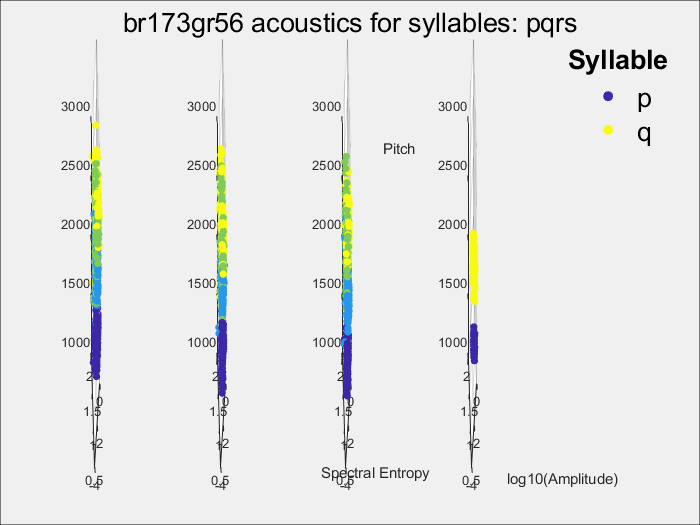

lgd.Title.String = 'Syllable';
lgd.Title.FontSize = 16;
% colormap("turbo")
xlabel(lbl_x); ylabel(lbl_y); zlabel(lbl_z)
hlink = linkprop(ax,{'CameraPosition','CameraUpVector','CameraTarget','View','CameraPositionMode',...
    'Xlim','Ylim','Zlim','PlotBoxAspectRatio'});
rotate3d on

## Scatter Plot Matrices - multiple syllables in one plot

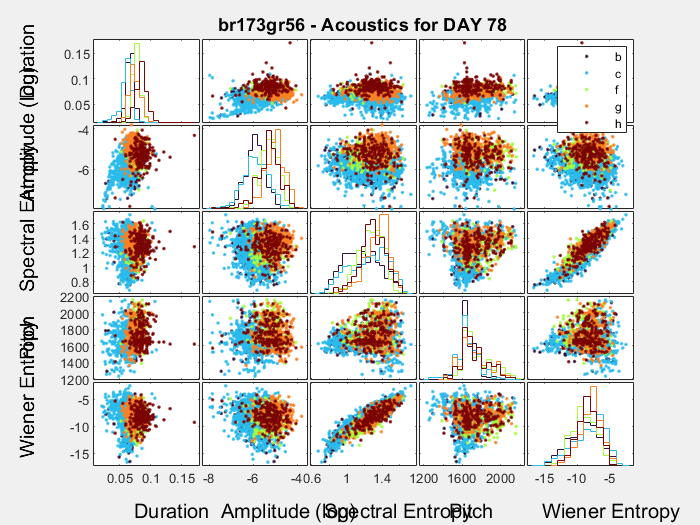

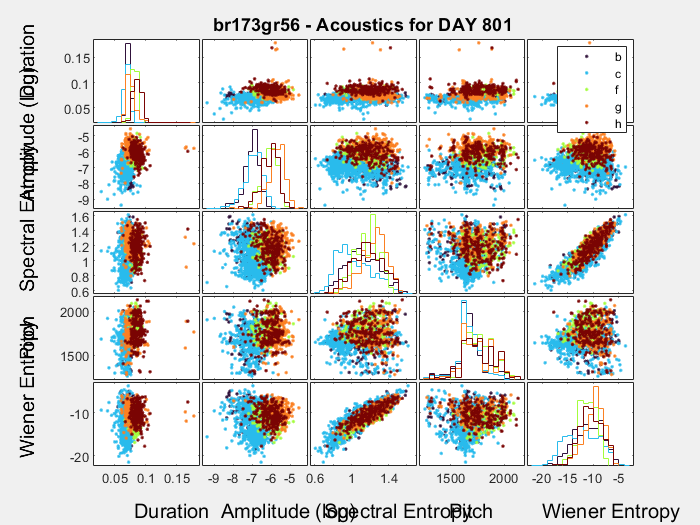

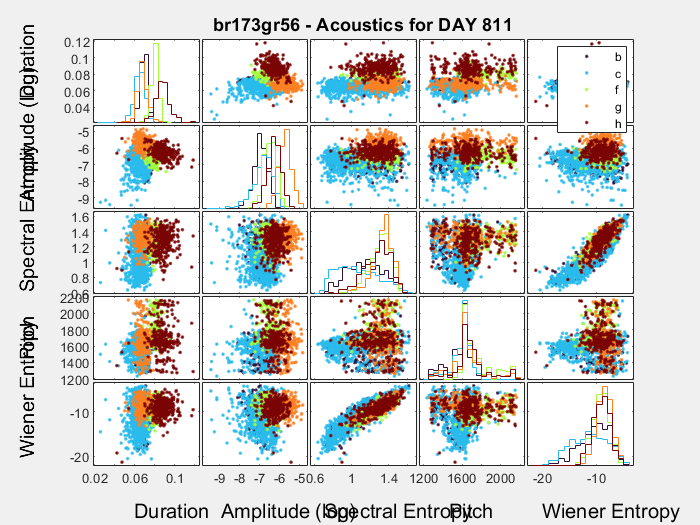

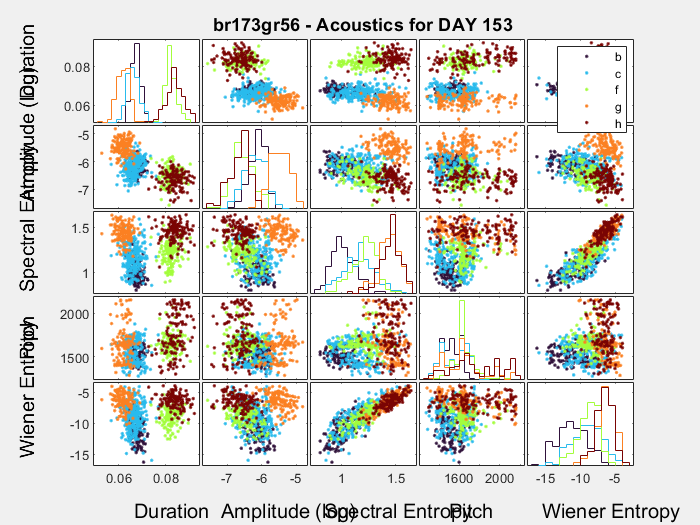

clear all
syls = ['bcfgh']; 
day = [78 801 811 153];
bird = 'br173gr56';
numvars = 5; % how many variables are you plotting
varNames = {'Duration'; 'Amplitude (log)';'Spectral Entropy';'Pitch'; 'Wiener Entropy'};

% Plot Placements of X and Y variable Names - manually change when varying
% the number of variables plotted

x_lbl = [.08 .24 .43 .66 .83]; y_lbl = [.86 .62 .41 .25 .02]; % optimal for 5 vars


plotvar = strings(length(varNames),1);
for a = 1:length(varNames)
    if contains(varNames(a),'duration',"IgnoreCase",true)
        plotvar(a) = 'syl_dur';
        limits = [0 0.14];
    elseif contains(varNames(a),'amplitude',"IgnoreCase",true)
        plotvar(a) = 'amp_at_pitchquant';
        limits = [-8 0];
    elseif contains(varNames(a),'spectral',"IgnoreCase",true)
        plotvar(a) = 'spect_entropy';
        limits = [0.25 1.75];
    elseif contains(varNames(a),'pitch',"IgnoreCase",true)
        plotvar(a) = 'peak_pinterp';
        limits = [1500 3000];
    elseif contains(varNames(a), 'wiener',"IgnoreCase",true)
        plotvar(a) = 'wiener_entropy';
        limits = [-40 -5];
    end
end

% Load acoustics data and save a table for each day_syllable data
for d = 1:length(day)
    
    [~,~,~,folder,recdate] = raster_params(bird,day(d));
    cd(folder)

    for s=1:length(syls)
        try
        fn_syl = sprintf('%s_%s_syl_%s.mat',bird,recdate,syls(s));
        load(fn_syl,'syl_sum');
        eval(sprintf('day%d_%s = syl_sum;',day(d),syls(s)));
        end
    end
end

% Load acoustics data and save a table for each day_syllable data
for d = 1:length(day)
    [~,~,~,folder,recdate] = raster_params(bird,day(d));
    cd(folder)
    
    eval(sprintf('day%d = table;',day(d)))
    for s=1:length(syls)
        fn_syl = sprintf('%s_%s_syl_%s.mat',bird,recdate,syls(s));
        load(fn_syl,'syl_sum');
        eval(sprintf('day%d_%s = syl_sum;',day(d),syls(s)));
        eval(sprintf('temp = day%d_%s;', day(d),syls(s)))
        eval(sprintf('day%d = vertcat(day%d, day%d_%s);',day(d),day(d),day(d),syls(s)))
    end
    
    % Create vector of syllables for color labeling
    eval(sprintf("len%d = size(day%d,1); syls%d = cell2mat(day%d.syllable);",...
        day(d),day(d),day(d),day(d)));
    
    % Create array for plotting
    X = [];
    for b = 1:length(varNames)
        eval(sprintf('ac%d = day%d.%s;', b, day(d),plotvar(b)))
        if contains(plotvar(b),'amp')
            eval(sprintf('ac%d = log(day%d.%s);', b, day(d),plotvar(b)))
        end
        eval(sprintf('X = horzcat(X,ac%d);', b))
    end
    
    clr = turbo(length(syls));
    sizen = repmat(numvars,numvars,1); %assign size to first value

    % Plot Matrix for given day
    g(d) = figure; set(g(d), 'Visible', 'on')
    eval(sprintf('gplotmatrix(X,[],syls%d,clr,[],sizen,[])',day(d)));
    title(sprintf('%s - Acoustics for DAY %d', bird,(day(d))))
    text(x_lbl(1:numvars), repmat(-.1,1,numvars), varNames, 'FontSize',12);
    text(repmat(-.12,1,numvars), y_lbl(1:numvars), varNames, 'FontSize',12, 'Rotation',90);
end

## Scatter Plot Matrices - 1 syllable, multiple days in one plot

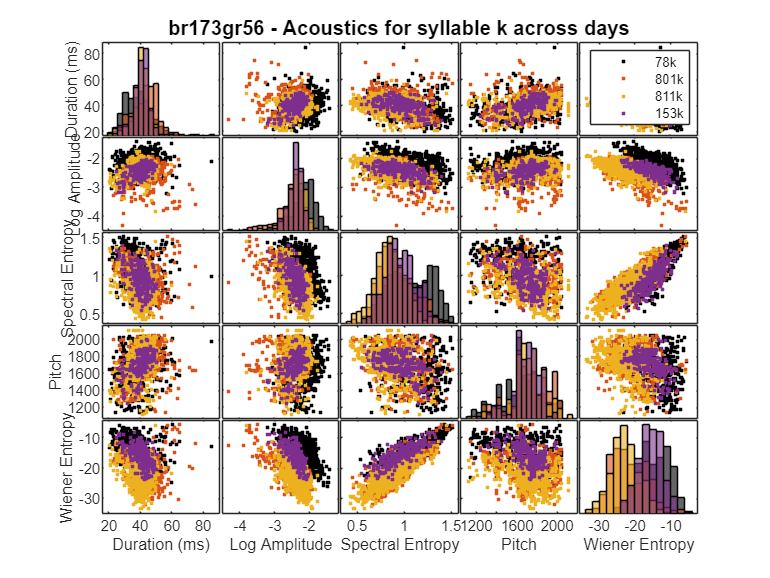

clear all
syls = ['k']; 
day = [78 801 811 153];
bird = 'br173gr56';
varNames = {'Duration (ms)', 'Log Amplitude','Spectral Entropy','Pitch', 'Wiener Entropy'};
numvars = length(varNames); % how many variables are you plotting

% Plot Placements of X and Y variable Names - manually change when varying
% the number of variables plotted
g = figure; set(g, 'Visible', 'on')
x_lbl = [.08 .24 .43 .66 .83]; y_lbl = [.86 .62 .41 .25 .02]; % optimal for 5 vars


% Data table that will store acoustics for all the days
allAcoustics = table;
allLabels = [];
for s = 1:length(syls)
    for d = 1:length(day)
    
        % load acoustic data for syllable for day(d) and store in allAcoustics
        [~,~,~,folder,recdate] = raster_params(bird,day(d));
        cd(folder)
        fn_syl = sprintf('%s_%s_syl_%s.mat',bird,recdate,syls(s));
        load(fn_syl,'syl_sum');
        syl_sum.day = repmat(day(d),size(syl_sum,1),1);
        allAcoustics = vertcat(allAcoustics,syl_sum);
    
        % % Create GROUP vector of syllables for color labeling
        % if day(d) < 100
        %     label_day = repmat(string(strcat(num2str(day(d)),syls(s))),size(syl_sum,1),1);
        % elseif day(d) > 500
        %     dayname = num2str(day(d));
        %     label_day = repmat(string(strcat(dayname(1:2),syls(s))),size(syl_sum,1),1);
        % % else
        % %     label_day = repmat([num2str(day(d)) ' '],size(syl_sum,1),1);
        % end
        % allLabels = vertcat(allLabels,label_day);
    end
end

% Create GROUP vector of syllables for color labeling
allDays = allAcoustics.day; 
allSyls = allAcoustics.syllable;
allLabels = cell(1, length(allDays)); % Preallocate cell array for combined strings
% Loop through each index and combine the elements
for i = 1:length(allDays)
    allLabels{i} = sprintf('%d%s', allDays(i), allSyls{i});
end
allLabels = string(allLabels)';

% Designate X and Y Plots
plotvar = strings(length(varNames),1);
limits = [];
X = [];
for a = 1:length(varNames)
    if contains(varNames(a),'duration',"IgnoreCase",true)
        plotvar(a) = 'syl_dur';
        limits(a,1:2) = [0 0.14];
        duration = allAcoustics.syl_dur;
        X(:,a) = duration*1000;
    elseif contains(varNames(a),'amplitude',"IgnoreCase",true)
        plotvar(a) = 'amp_at_pitchquant';
        amplitude = allAcoustics.amp_at_pitchquant;
        X(:,a) = log10(amplitude);
        amplitude = allAcoustics.amp_at_pitchquant;
        limits(a,1:2) = [-8 0];
    elseif contains(varNames(a),'spectral',"IgnoreCase",true)
        plotvar(a) = 'spect_entropy';
        limits(a,1:2) = [0.25 1.75];
        spectral_entropy = allAcoustics.spect_entropy;
        X(:,a) = spectral_entropy;
    elseif contains(varNames(a),'pitch',"IgnoreCase",true)
        plotvar(a) = 'peak_pinterp';
        limits(a,1:2) = [1500 3000];
        pitch = allAcoustics.peak_pinterp;
        X(:,a) = pitch;
    elseif contains(varNames(a), 'wiener',"IgnoreCase",true)
        plotvar(a) = 'wiener_entropy';
        limits(a,1:2) = [-40 -5];
        wiener_entropy = allAcoustics.wiener_entropy;
        X(:,a) = wiener_entropy;
    end
end

clr = lines(length(unique(allLabels))); 
clr(1,:) = [0 0 0];
figure(124);clf
gplotmatrix(X,[],string(allLabels),clr,".",6,[],'grpbars',varNames)
    title(sprintf('%s - Acoustics for syllable %s across days', bird,syls))

%     text(x_lbl(1:numvars), repmat(-.1,1,numvars), varNames, 'FontSize',10);
%     text(repmat(-.12,1,numvars), y_lbl(1:numvars), varNames, 'FontSize',10, 'Rotation',90);


% Plot just pitch histogram
figure(124);clf; hold on
day68 = spectral_entropy(1:449);
day73 = spectral_entropy(450:end);
% day88_low = day88(day88 < 2580);
% day88_hi = day88(day88 >= 2580);
xlo = 0.3;
xhi = 1.8;

[n1,bins1] = histcounts(day68,xlo:0.1:xhi);
[n2,bins2] = histcounts(day73,xlo:0.1:xhi);
% [n3,bins3] = histcounts(day88_low,2200:50:3000);
% [n4,bins4] = histcounts(day88_hi,2200:50:3000);

p1 = plot(bins1(1:end-1),n1/length(day68));
p1.Color = '#7F7F7F';
p1.LineWidth = 3;
p2 = plot(bins2(1:end-1),n2/length(day73));
p2.Color = '#6BB3B6';
p2.LineWidth = 3;
% p3=plot(bins4(1:end-1),n4/length(day88_hi));
% p3.Color = '#EA63C2';
% p3.LineWidth = 3;

xlim([xlo xhi])
xlabel(['Spectral Entropy'])
ylabel(['Probability'])

fontname = 'Franklin Gothic Heavy';
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')

% Plot just pitch histogram
figure(124);clf; hold on
day68 = pitch(1:449);
day73 = pitch(450:end);
% day88_low = day88(day88 < 2580);
% day88_hi = day88(day88 >= 2580);

[n1,bins1] = histcounts(day68,1500:50:2500);
[n2,bins2] = histcounts(day73,1500:50:2500);
% [n3,bins3] = histcounts(day88_low,2200:50:3000);
% [n4,bins4] = histcounts(day88_hi,2200:50:3000);

p1 = plot(bins1(1:end-1),n1/length(day68));
p1.Color = '#7F7F7F';
p1.LineWidth = 3;
p2 = plot(bins2(1:end-1),n2/length(day73));
p2.Color = '#6BB3B6';
p2.LineWidth = 3;
% p3=plot(bins4(1:end-1),n4/length(day88_hi));
% p3.Color = '#EA63C2';
% p3.LineWidth = 3;

xlim([1500 2500])
xlabel(['Pitch (Hz)'])
ylabel(['Probability'])

fontname = 'Franklin Gothic Heavy';
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')


% Plot just pitch histogram

figure(123);clf; hold on
day68 = pitch(1:897);
day88 = pitch(897:end);
day88_low = day88(day88 < 2580);
day88_hi = day88(day88 >= 2580);

[n1,bins1] = histcounts(day68,2200:50:3000);
[n2,bins2] = histcounts(day88,2200:50:3000);
[n3,bins3] = histcounts(day88_low,2200:50:3000);
[n4,bins4] = histcounts(day88_hi,2200:50:3000);

p1 = plot(bins1(1:end-1),n1/length(day68));
p1.Color = '#A98EA5';
p1.LineWidth = 3;
p2 = plot(bins3(1:end-1),n3/length(day88_low));
p2.Color = '#FF9538';
p2.LineWidth = 3;
p3=plot(bins4(1:end-1),n4/length(day88_hi));
p3.Color = '#EA63C2';
p3.LineWidth = 3;

xlim([2200 3000])
xlabel(['Pitch (Hz)'])
ylabel(['Probability'])

fontname = 'Franklin Gothic Heavy';
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')


## STEP 3: Quantify Acoustics with PCA

For a given syllable, create a matrix of the spectrogram power for each frequency bin (columns) for each syllable trial (row). 

bird = 'br177yw112';
syls = 'bk';
days = [62 68 73 88];
dims = 'acparams'; % dimensions to analyze: acparams, spec_slice, or spec_allfreqs;

% Collate matrices for all days
allSylDays = [];
groupID = [];
for s = 1:length(syls)
    allDays = [];
    for d = 1:length(days)
        try
        % load acoustic data for syllable for day(d) and store in allAcoustics
        [~,~,~,folder,recdate] = raster_params(bird,days(d));
        cd(folder)
        fn_syl = sprintf('%s_%s_syl_%s.mat',bird,recdate,syls(s));
        load(fn_syl);
    
        % Create the matrix with the dimension type of choice
        switch dims
            case 'acparams'
                datamatrix = syl_sum(:,[5,12:15]); datamatrix = table2array(datamatrix); 
%                 datamatrix(:,3) = log(syl_sum.amp_sm_window);
                cats = syl_sum.Properties.VariableNames([5,12:15]); 
            case 'spec_slice'
                datamatrix = P1_save;
                cats = string(1:1:size(datamatrix,2));
            case 'spec_allfreqs'
                datamatrix = P1_save_allfreqs; %each row is spectrogram slice's power for 1 syllable
                cats = string(1:1:size(datamatrix,2));
        end
        
        groupId = repmat([num2str(days(d)) syls(s)],size(fn_syl,1),1);
        allDays = vertcat(allDays,datamatrix);
        catch
            message = ['failed for: ' num2str(days(d)) ' -syl ' syls(s)];
            disp(message)
        end
    end

    allSylDays = vertcat(allSylDays,allDays);
end

figure(); boxplot(zscore(allSylDays),'Orientation','horizontal','Labels',cats)   
title(sprintf('syllable %s, z-scored acoustics across days: %s',syls,num2str(days)))

% run_pca(zscore(allDays),cats,0)
run_pca(allSylDays,cats,1)


function run_pca(matrix,cats,weighting)

%Check Pairwise Correlation between columns
C = corr(matrix,matrix)

% Compute PCs
    % coeff = eigenvectors of the covariance matrix
    % score = data * eigenvectors (i.e. projections on the PC vector space)
    % latent = eigenvalues of the covariance matrix (i.e. the variances of the
    % vectors)
    % explained = % variance explained by each PC
% w = 1./var(allDays); %use the inverse variances of the data as weights
if weighting == 1
    [wcoeff, score, latent, tsquared, explained] = pca(matrix,...
        'VariableWeights','variance');

    % Take the coff vectors of the first 3 PCs. 
    c3 = wcoeff(:,1:3); %these are weighted, therefore not orthonormal

    % Transform coefficients so that they are orthonormal
    coeff = diag(std(matrix))\wcoeff;
    
    % Check that transformed coefficients are orthonormal
    I = coeff'*coeff;
    I(1:3,1:3)

elseif weighting == 0
    [coeff, score, latent, tsquared, explained] = pca(matrix);
    I = coeff'*coeff;
    I(1:3,1:3)
end

% Plot component scores
figure
plot(score(:,1),score(:,2),'+','Color','red'); 
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
pts = gname; %plot outliers
getpts = get(pts,{'string'});
points = cellfun(@str2double,getpts,'UniformOutput',false);
points = cat(1,points{:})



% Component Variances
latent

% Make Scree plot
figure; pareto(explained);
xlabel('PC')
ylabel('Variance Explained (%)')

% Find the most extreme points using Hotelling's T-squared Statistic
[st2, index] = sort(tsquared,'descend');
extreme_idx = index(1)

% Biplot: Visualizes both the orthonormal PC coeffs for each variable and the PC
% scores for each data point
figure %2 PCs
biplot(coeff(:,1:2),'Scores',score(:,1:2),'Varlabels',cats)

figure %3 PCs
biplot(coeff(:,1:3),'Scores',score(:,1:3),'VarLabels',cats)

end

function zscore_pca(matrix)
    % Do the PCA
    % coeff = eigenvectors of the covariance matrix
    % score = data * eigenvectors (i.e. projections on the PC vector space)
    % latent = eigenvalues of the covariance matrix (i.e. the variances of the
    % vectors)
    % explained = % variance explained by each PC
    
    [coeff,score,latent,tsquared,explained,mu] = pca(matrix) ;
    
    % Visualize the data representation in the space of the first three principal components.
    figure; scatter3(score(:,1),score(:,2),score(:,3));
    axis equal
    xlabel('1st Principal Component')
    ylabel('2nd Principal Component')
    zlabel('3rd Principal Component')
    
    % Visualize both the orthonormal principal component coefficients for each variable and the principal component scores for each observation in a single plot.
    figure;biplot(coeff(:,1:2),'scores',score(:,1:2));
    
    % Visualize the cumulative contribution of each PC
%     figure;plot(cumsum(explained(1:3)),'-');
    figure; pareto(explained);
    xlabel('PC')
    ylabel('Variance Explained (%)')
end